# Chapter 1 - Exploratory Data Analysis

以下は、「データサイエンスのための統計学入門」（Peter Bruce, Andrew Bruce、原題 Practical Statistics for Data Scientists）の第１章：探索的データ解析を MATLAB で実行した例です。

もともとの R コードはこちら（[GitHub](https://github.com/andrewgbruce/statistics-for-data-scientists)）にあり、データも著者によって [Google Drive](https://drive.google.com/drive/folders/0B98qpkK5EJemYnJ1ajA1ZVJwMzg) もしくは [Dropbox](https://www.dropbox.com/sh/clb5aiswr7ar0ci/AABBNwTcTNey2ipoSw_kH5gra?dl=0) から入手可能です。データファイル（csv）はすべてフォルダ ..\psds_data 内にあるとします。

### 実行環境

- MATLAB R2020a

- Statistics and Machine Learning Toolbox

## 1.3.3 例: 人口と殺人事件発生率の代表値の推定

注意：R2019a 以前のバージョンでは `Murder.Rate` は MATLAB の変数名としては使えないので読み込み時に `Murder_Rate` に変更されます（警告が出ます）。

変数名を付けてデータの読み込む場合は `readtable` 関数（[doc](https://jp.mathworks.com/help/matlab/ref/readtable.html)）が便利。

state = readtable('..\psds_data\state.csv');

州別人口と殺人事件発生率の最初の数行（表 1.2）を確認します。

head(state)

ans = 8×4 table
         State         Population    Murder_Rate    Abbreviation
    _______________    __________    ___________    ____________

    {'Alabama'    }    4.7797e+06        5.7           {'AL'}   
    {'Alaska'     }    7.1023e+05        5.6           {'AK'}   
    {'Arizona'    }     6.392e+06        4.7           {'AZ'}   
    {'Arkansas'   }    2.9159e+06        5.6           {'AR'}   
    {'California' }    3.7254e+07        4.4           {'CA'}   
    {'Colorado'   }    5.0292e+06        2.8           {'CO'}   
    {'Connecticut'}    3.5741e+06        2.4           {'CT'}   
    {'Delaware'   }    8.9793e+05        5.8           {'DE'}   


**参考**：R2019b 以降は `'PreserveVariableNames'` を `'true'` に設定するとそのまま変数名として使えますが、呼び出し方が多少不便。

tmp = readtable('state.csv','PreserveVariableNames',true);
tmp.("Murder.Rate");

### 人口の平均値、トリム平均、中央値を計算

簡単な統計値を計算してみます。まずは平均値と中央値はそれぞれ `mean` 関数と `median` 関数で計算します。

popMean = mean(state.Population)

popMean = 6.1629e+06

popMedian = median(state.Population)

popMedian = 4.4364e+06

トリム平均はデータの両端を取り除いたデータの平均値です。外れ値に対して影響を受けにくくなります。例えば上位 10%、下位 10 % を取り除くトリム平均は以下。

% 両端合わせて 20% = 10 州取り除く
popTrimMean = trimmean(state.Population,20) % 要 Statistics and Machine Learning Toolbox

popTrimMean = 4.7837e+06

人口のヒストグラム表示には `histogram` 関数（[doc](https://jp.mathworks.com/help/matlab/ref/matlab.graphics.chart.primitive.histogram.html)）を使用。各平均値をプロットしてみます・・そんなに変わらないですね。

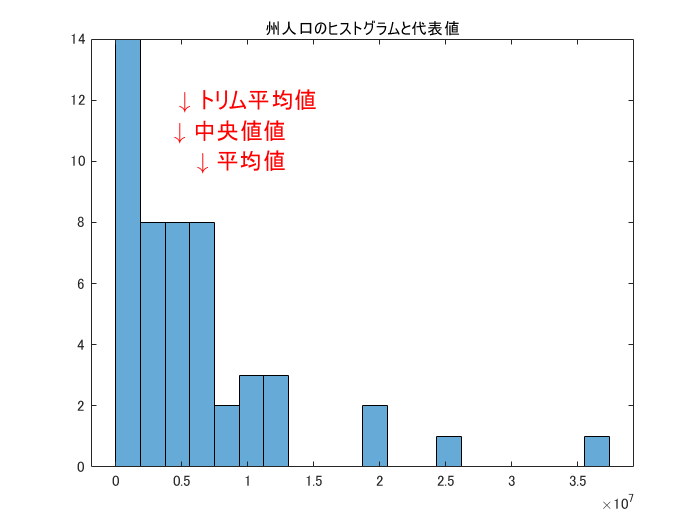

figure
histogram(state.Population,20)
title("州人口のヒストグラムと代表値")
text(popMean,10,'\downarrow 平均値','Color','red','FontSize',14)
text(popMedian,11,'\downarrow 中央値値','Color','red','FontSize',14)
text(popTrimMean,12,'\downarrow トリム平均値','Color','red','FontSize',14)

### 平均殺人事件発生率：加重平均、加重中央値

加重平均は重みをかけたベクトルに `mean` 関数です。

wMean = mean(state.Murder_Rate.*state.Population/mean(state.Population))

wMean = 4.4458

加重中央値はデータをソートし、それぞれの重みの総和が真ん中に相当する位置にあるデータを見つける処理をします。ちょっとややこしい。

[sortedRate,idx] = sort(state.Murder_Rate); % データのソート
weight = state.Population/sum(state.Population); % 重み
sortedWeight = weight(idx); % データ順に並べ替えた重み
idxMedian = find(cumsum(sortedWeight)>sum(weight)/2,1); % 半分以上の位置（index）
wMedian = sortedRate(idxMedian)

wMedian = 4.4000

上と同じようにヒストグラムで確認してみます。あまり変わらず。

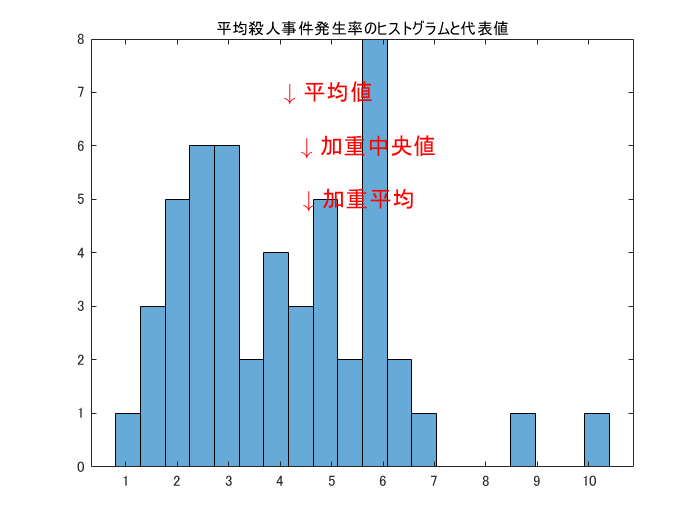

figure
histogram(state.Murder_Rate,20)
title("平均殺人事件発生率のヒストグラムと代表値")
text(wMean,5,'\downarrow 加重平均','Color','red','FontSize',14)
text(wMedian,6,'\downarrow 加重中央値','Color','red','FontSize',14)
text(mean(state.Murder_Rate),7,'\downarrow 平均値','Color','red','FontSize',14)

## 1.4.3 例：州別人口の散らばりの推定

標準偏差（`std` 関数）、四分位範囲（`iqr` 関数）、中央値絶対偏差（`mad` 関数）を計算しますが、R での計算結果との違いに注意。

popStd = std(state.Population)

popStd = 6.8482e+06

popIQR = iqr(state.Population) % 要 Statistics and Machine Learning Toolbox

popIQR = 4898199

これは0.75 分位数から 0.25 分位数を引いたものと同じ。

popQ = quantile(state.Population,0.75)-quantile(state.Population,0.25)

popQ = 4898199

MATLAB の `mad` 関数は平均値絶対偏差 (`flag = 0`、既定) か中央値絶対偏差 (`flag = 1`) を計算します。中央値絶対偏差の定義は `median(abs(X – median(X)))` です。

popMad = mad(state.Population,1) % 要 Statistics and Machine Learning Toolbox

popMad = 2596702

一応検算。

median(abs(state.Population-median(state.Population)))

ans = 2596702

## 1.5.1 パーセンタイルと箱ひげ図

州別の殺人事件発生率のパーセンタイル（表1.4）を表示してみます。

quantile(state.Murder_Rate,[0.05 0.25 0.50 0.75 0.95])

ans =     1.6000    2.4000    4.0000    5.6000    6.6000


州別人口の箱ひげ図（図1.2）で外れ値など確認しやすくなります。

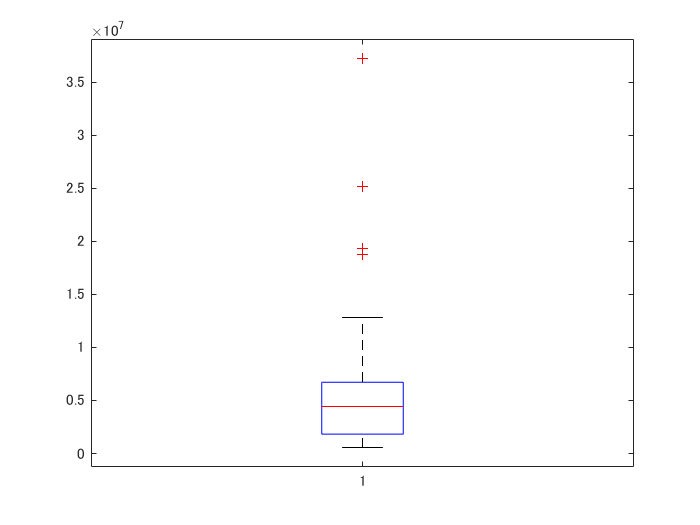

boxplot(state.Population)

以前より `boxplot` という関数が Statistics and Machine Learning Toolbox にありますが、R2020a からは `boxchart` という関数が MATLAB 本体で使えます。`boxchart` 関数（[doc](https://www.mathworks.com/help/matlab/ref/boxchart.html)）の方が見栄えを調整しやすくなっています。

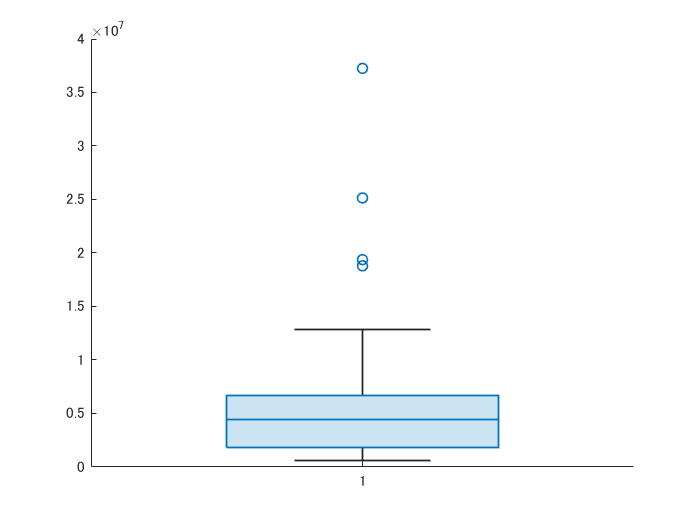

if ~verLessThan('matlab','9.8')
    % -- Code to run in MATLAB R2020a and later here --
    boxchart(state.Population)
end

## 1.5.2 度数分布表とヒストグラム

ビンの幅を指定して各ビンの度数（データ数）を算出します。`histocounts` 関数が使えます。

edges = linspace(min(state.Population), max(state.Population), 11);
[N, ~, bin] = histcounts(state.Population,edges);

bin に各州がどのビンに入っているかの情報がはいります。例えば

join(state.Abbreviation(bin==3))

ans = 1×1 の cell 配列
    {'GA MI NJ NC OH VA'}


といった感じ。ですので州別人口の度数分布表（表1.5 ）を再現するなら・・

histTable = [];
for binID=1:10
    binRange = [edges(binID), edges(binID+1)];
    counts = N(binID);
    stateList = join(state.Abbreviation(bin==binID));
    histTable = [histTable; table(binID, binRange, counts, stateList)];
end
histTable

histTable = 10×4 table
    binID            binRange            counts                                     stateList                                 
    _____    ________________________    ______    ___________________________________________________________________________

      1      5.6363e+05    4.2327e+06      24      {'AK AR CT DE HI ID IA KS ME MS MT NE NV NH NM ND OK OR RI SD UT VT WV WY'}
      2      4.2327e+06    7.9017e+06      14      {'AL AZ CO IN KY LA MD MA MN MO SC TN WA WI'                              }
      3      7.9017e+06    1.1571e+07       6      {'GA MI NJ NC OH VA'                                                      }
      4      1.1571e+07     1.524e+07       2      {'IL PA'                                                                  }
      5       1.524e+07    1.8909e+07       1      {'FL'                                                                     }
      6      1.8909e+07    2.2578e+07       1      {'NY'                               

ヒストグラムを書くなら `hisgtogram` 関数。

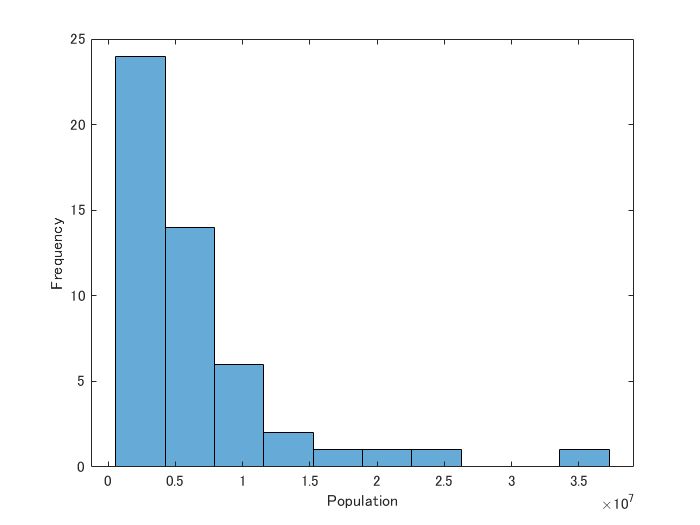

histogram(state.Population, edges)
xlabel('Population')
ylabel('Frequency')

## 1.5.3 密度推定

カーネル密度を推定するなら ksdensity 関数（[doc](https://jp.mathworks.com/help/stats/ksdensity.html)）。標本データに対する確率密度推定値を計算します。

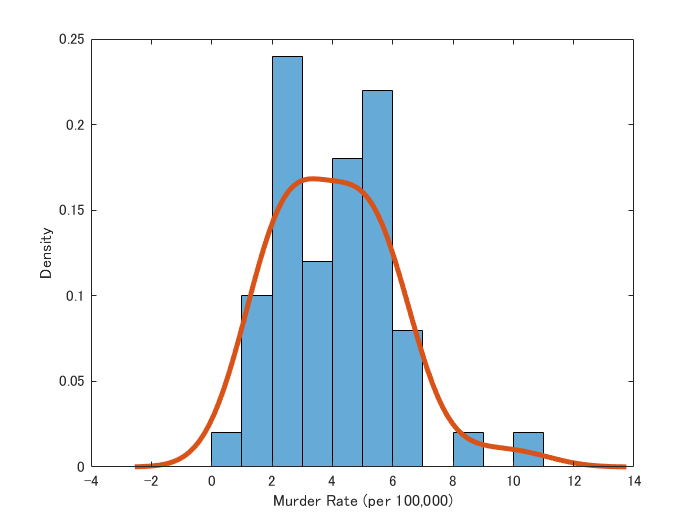

histogram(state.Murder_Rate,[0:12],'Normalization',"pdf")
hold on
[f,xi] = ksdensity(state.Murder_Rate);
plot(xi,f,'LineWidth',3);
hold off
xlabel('Murder Rate (per 100,000)')
ylabel('Density')

## 1.6 バイナリデータとカテゴリデータの探索

ダラス空港の原因別飛行機遅延のデータを使用します。まずは `readtable` で読み込み。

asdfw = readtable("..\psds_data/dfw_airline.csv")

asdfw = 1×5 table
    Carrier     ATC     Weather    Security     Inbound  
    _______    _____    _______    ________    __________

     64263     84857     11235      343.15     1.1843e+05


棒グラフで原因別の遅延回数をプロットします。

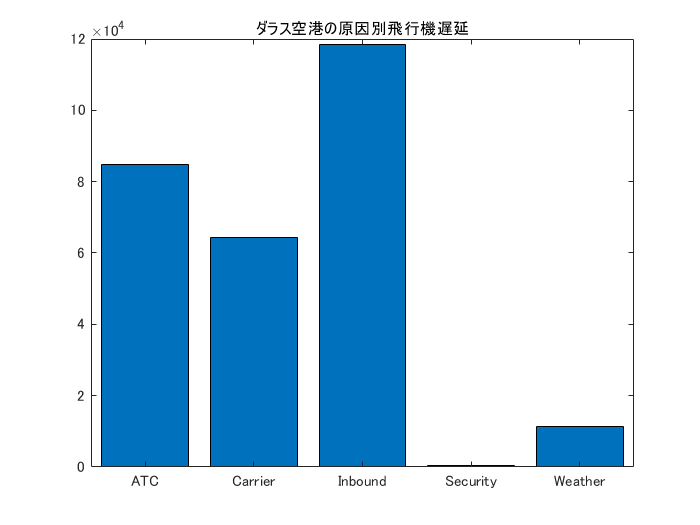

x = asdfw.Properties.VariableNames;
y = asdfw.Variables;
bar(categorical(x),y) % x 座標データはカテゴリー型変数で。
title("ダラス空港の原因別飛行機遅延")

## 1.7 相関

データの相関について。ここでは `sp500_data.csv` と `sp500_sectors.csv` の株価情報を取り扱います。

### データ読み込み

sp500DailyReturns = readtable("..\psds_data/sp500_data.csv"); % S&P 500 Daily Returns

sp500Symbols = readtable("..\psds_data/sp500_sectors.csv"); % Selected S&P Symbols

### データの前処理

データの一部冒頭だけ確認しておきます。`sp500DailyReturns` は各銘柄の株価変化率。

head(sp500DailyReturns(:,1:5))

ans = 8×5 table
       Var1       ADS       CA         MSFT       RHT
    __________    ___    ________    _________    ___

    1993-01-29     0     0.060124      -0.0221     0 
    1993-02-01     0     -0.18039     0.027621     0 
    1993-02-02     0     -0.12026       0.0359     0 
    1993-02-03     0     0.060124    -0.024857     0 
    1993-02-04     0     -0.36077    -0.060757     0 
    1993-02-05     0     0.030058     0.093892     0 
    1993-02-08     0     0.030066     -0.06075     0 
    1993-02-09     0     -0.09019    -0.063521     0 


1993 年からの情報が入っていますが、ここでは 2012年7月1日以降のデータのみを使用します。`timetable` 型を使うと便利。

まず変数名 `Var1` で読み込んでいる日付情報を時間データとして `timetable` 型に変換。その後 2012/7/1 の日付以降のデータを以下のように抽出。

sp500Returns = table2timetable(sp500DailyReturns,'RowTimes',"Var1");
sp500Returns2012 = sp500Returns(sp500Returns.Var1 > datetime(2012,7,1),:);

次に `sp500Symbols` は銘柄のセクターやティッカー名などの情報が入っています。

head(sp500Symbols)

ans = 8×4 table
              sector               sector_label                    sub_sector                     symbol 
    __________________________    ______________    _________________________________________    ________

    {'information_technology'}    {'Technology'}    {'data_processing_&_outsourced_services'}    {'ADS' }
    {'information_technology'}    {'Technology'}    {'systems_software'                     }    {'CA'  }
    {'information_technology'}    {'Technology'}    {'systems_software'                     }    {'MSFT'}
    {'information_technology'}    {'Technology'}    {'systems_software'                     }    {'RHT' }
    {'information_technology'}    {'Technology'}    {'it_consulting_&_services'             }    {'CTSH'}
    {'information_technology'}    {'Technology'}    {'it_consulting_&_services'             }    {'CSC' }
    {'information_technology'}    {'Technology'}    {'it_consulting_&_services'             }    {'EMC' }
    {'information_technology'

ここでは Sector が Telecom の銘柄に注目。`sector_label` が文字列が入ったセル配列である点に注意。いったん string 型に変換して == で処理しやすいくしています。

symbolsTelecom = sp500Symbols.symbol(string(sp500Symbols.sector_label) == 'Telecom')

symbolsTelecom = 5×1 の cell 配列
    {'T'   }
    {'CTL' }
    {'FTR' }
    {'VZ'  }
    {'LVLT'}


これらのティッカーの情報だけ取り出すには・・

telecom2012 = sp500Returns2012(:,symbolsTelecom);
head(telecom2012)

ans = 8×5 timetable
       Var1          T          CTL          FTR           VZ          LVLT   
    __________    ________    ________    __________    _________    _________

    2012-07-02      0.4225     0.14085      0.070879      0.55418        -0.52
    2012-07-03    -0.17745     0.06628      0.070879    -0.025976    -0.049999
    2012-07-05    -0.16055    -0.13256      0.055128    -0.051956        -0.18
    2012-07-06      0.3422     0.13256     0.0078755      0.14011        -0.36
    2012-07-09     0.13688     0.12428     -0.023626      0.25394         0.18
    2012-07-10    -0.22244    -0.19056     -0.031502     -0.17513        -0.62
    2012-07-11    -0.13688     0.35626      0.039377      0.14011    -0.030001
    2012-07-12    -0.14544     0.26513    -0.0078755      0.01751         0.08


とれました。

### 通信分野の株式収益の相関

ようやく通信分野の株式収益の相関を計算しますが、`corrcoef` 関数（[doc](https://jp.mathworks.com/help/matlab/ref/corrcoef.html)）を使用します。

corrTelcom = corrcoef(telecom2012.Variables) % ヒント：telecom2012.Variable で数値データだけを抽出しています。

corrTelcom =     1.0000    0.4747    0.3278    0.6776    0.2786
    0.4747    1.0000    0.4198    0.4166    0.2867
    0.3278    0.4198    1.0000    0.2874    0.2601
    0.6776    0.4166    0.2874    1.0000    0.2422
    0.2786    0.2867    0.2601    0.2422    1.0000


数値の羅列だけだと不親切なので、表形式にしてみます。

array2table(corrTelcom,'VariableNames', symbolsTelecom, "RowNames",symbolsTelecom)

ans = 5×5 table
               T         CTL        FTR        VZ        LVLT  
            _______    _______    _______    _______    _______

    T             1    0.47468    0.32777    0.67761    0.27863
    CTL     0.47468          1    0.41976     0.4166    0.28667
    FTR     0.32777    0.41976          1    0.28739    0.26007
    VZ      0.67761     0.4166    0.28739          1     0.2422
    LVLT    0.27863    0.28667    0.26007     0.2422          1


### ETF 銘柄間の相関

今度は ETF を見てみます。 まずはティッカー名を取り出す。

symbolsETF = sp500Symbols.symbol(string(sp500Symbols.sector) == 'etf')

symbolsETF = 17×1 の cell 配列
    {'XLI'}
    {'QQQ'}
    {'SPY'}
    {'DIA'}
    {'GLD'}
    {'VXX'}
    {'USO'}
    {'IWM'}
    {'XLE'}
    {'XLY'}
    {'XLU'}
    {'XLB'}
    {'XTL'}
    {'XLV'}
    {'XLP'}
    {'XLF'}
    {'XLK'}


そしてそれぞれの ETF の株価収益率を取り出します。引き続き 2012/7/1 以降の情報のみを使います。

ETF2012 = sp500Returns2012(:,symbolsETF);

#### 散布図プロット行列

各銘柄同士の散布図をプロットするには `plotmatrix` 関数（[doc](https://jp.mathworks.com/help/matlab/ref/plotmatrix.html)）が使えます。

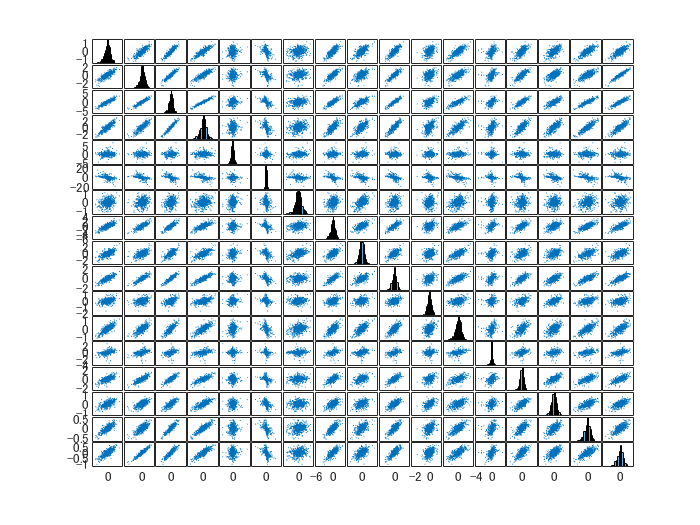

plotmatrix(ETF2012.Variables);

#### ヒートマップ

相関係数を計算するには corrcoef 関数（[doc](https://jp.mathworks.com/help/matlab/ref/corrcoef.html)）。heatmap 関数（[doc](https://jp.mathworks.com/help/matlab/ref/heatmap.html)）を使ったヒートマップ表示も分かりやすいです。

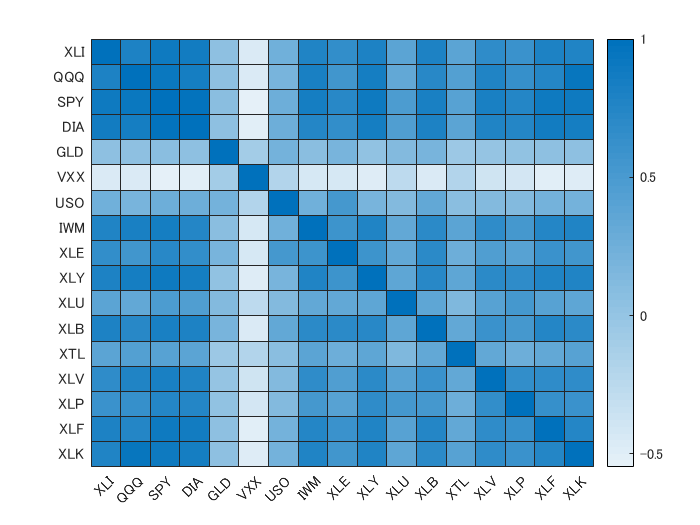

corrETF = corrcoef(ETF2012.Variables);
etfNames = ETF2012.Properties.VariableNames; % 表示名（ティッカー名）
heatmap(etfNames,etfNames,corrETF)

## 1.7.1 散布図

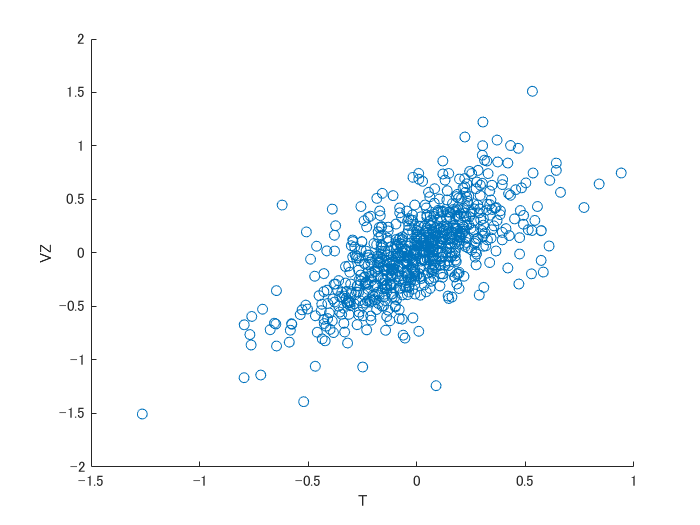

scatter(telcom.T, telcom.VZ)
xlabel("T");
ylabel("VZ")

## 1.8 2つ以上の変数の探索

## 1.8.1 6角ビニングと等高線（２つの数値データをプロット）

ここからは `kc_tax.csv` のデータ（）を使用します。

kingCountry = readtable('..\psds_data\kc_tax.csv');
head(kingCountry)

ans = 8×3 table
    TaxAssessedValue    SqFtTotLiving    ZipCode
    ________________    _____________    _______

             NaN            1730          98117 
        2.06e+05            1870          98002 
        3.03e+05            1530          98166 
        3.61e+05            2000          98108 
        4.59e+05            3150          98108 
        2.23e+05            1570          98032 
        2.59e+05            1770          98168 
        1.75e+05            1150          98168 


`ZipCode` (郵便番号)、 `TaxAssessedValue`（課税標準額）と `SqFtTotLiving`（床面積）のデータが確認できます。

ここで、非常に高額、広すぎる・狭すぎるデータは除きます。

tooExpensive = kingCountry.TaxAssessedValue > 750000;
tooBig = kingCountry.SqFtTotLiving > 3500;
tooSmall = kingCountry.SqFtTotLiving < 100;
subKingCountry = kingCountry(~tooExpensive & ~tooBig & ~tooSmall,:);
height(subKingCountry)

ans = 433838

binscatter 関数（[doc](https://jp.mathworks.com/help/matlab/ref/binscatter.html)） でデータの分布状況を可視化します。

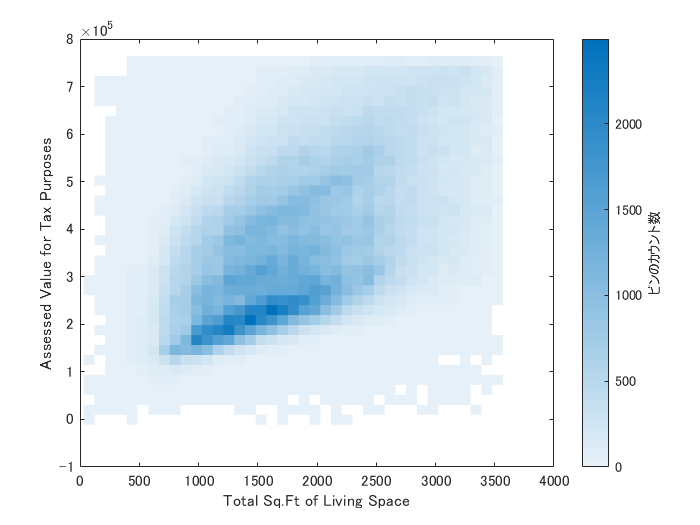

x = subKingCountry.SqFtTotLiving;
y = subKingCountry.TaxAssessedValue;
figure
binscatter(x,y);
xlabel('Total Sq.Ft of Living Space')
ylabel('Assessed Value for Tax Purposes')

2次元ヒストグラムも有効かもしれません。

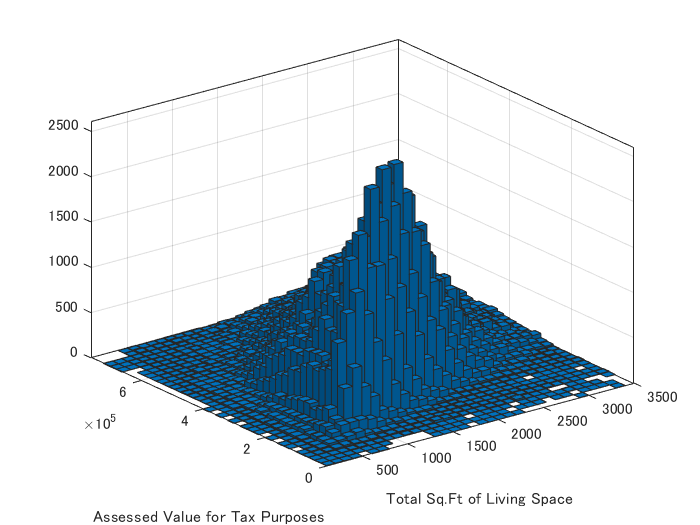

figure
histogram2(x,y)
xlabel('Total Sq.Ft of Living Space')
ylabel('Assessed Value for Tax Purposes')

散布図の上にデータの密度を等高線図で描くのも良いです。`histcount2` 関数（[doc](https://jp.mathworks.com/help/matlab/ref/histcounts2.html)）を使って二変量ヒストグラムのビンのカウント数を算出して等高線図を描きます。

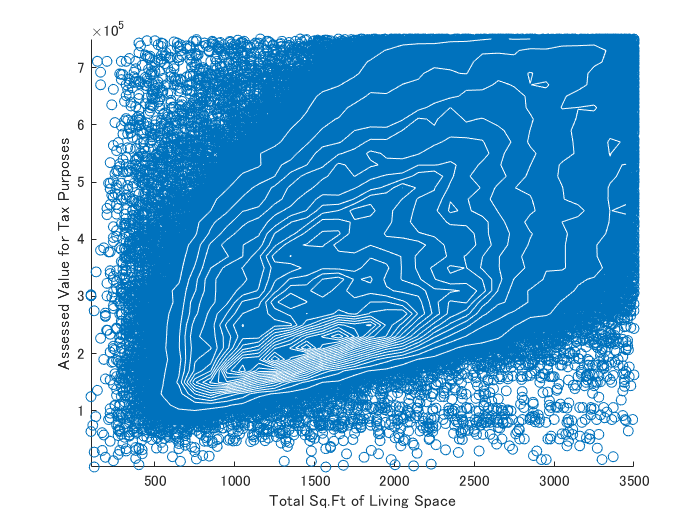

figure
scatter(x,y)
hold on
[N,Xedges,Yedges] = histcounts2(x,y);
Xcenter = (Xedges(1:end-1)+Xedges(2:end))/2; % 各ビンの両端の平均値（中央）
Ycenter = (Yedges(1:end-1)+Yedges(2:end))/2; % 各ビンの両端の平均値（中央）
[X,Y] = meshgrid(Xcenter,Ycenter);
contour(X,Y,N',20,'white')
hold off
xlabel('Total Sq.Ft of Living Space')
ylabel('Assessed Value for Tax Purposes')

## 1.8.2 2 つのカテゴリ変数の探索

ここでは `lc_loans.csv` を使用します。ローンの等級と支払い状況。

lc_loans = readtable("..\psds_data\lc_loans.csv");
height(lc_loans)

ans = 450961

head(lc_loans)

ans = 8×2 table
        status         grade
    _______________    _____

    {'Fully Paid' }    {'B'}
    {'Charged Off'}    {'C'}
    {'Fully Paid' }    {'C'}
    {'Fully Paid' }    {'C'}
    {'Current'    }    {'B'}
    {'Fully Paid' }    {'A'}
    {'Current'    }    {'C'}
    {'Fully Paid' }    {'E'}


こんなローンの等級とステータス（支払い状況）が入っていますので、それぞれカテゴリ型配列に変換したうえで crosstab 関数（[doc](https://jp.mathworks.com/help/stats/crosstab.html)）でクロス集計します。４つ目の出力（`labels`）で各ラベル名を確認できます。

lc_loans.grade = categorical(lc_loans.grade);
lc_loans.status = categorical(lc_loans.status);
[tmp,~,~,labels] = crosstab(lc_loans.grade,lc_loans.status)

tmp =         1562       50051       20408         469
        5302       93852       31160        2056
        6023       88928       23147        2777
        5007       53281       13681        2308
        2842       24639        5949        1374
        1526        8444        2328         606
         409        1990         643         199


labels = 7×2 の cell 配列
    {'A'}    {'Charged Off'}
    {'B'}    {'Current'    }
    {'C'}    {'Fully Paid' }
    {'D'}    {'Late'       }
    {'E'}    {0×0 double   }
    {'F'}    {0×0 double   }
    {'G'}    {0×0 double   }


数値行列だけでは味気ないので変数名も加えたテーブル型に変換。

array2table(tmp,'VariableNames',labels(1:4,2),"RowNames",labels(1:7,1))

ans = 7×4 table
         Charged Off    Current    Fully Paid    Late
         ___________    _______    __________    ____

    A       1562         50051       20408        469
    B       5302         93852       31160       2056
    C       6023         88928       23147       2777
    D       5007         53281       13681       2308
    E       2842         24639        5949       1374
    F       1526          8444        2328        606
    G        409          1990         643        199


## 1.8.3 カテゴリデータと数量データ

ここでは `airline_stats.csv` を使います。下記のように航空会社別の遅延情報が入っています。 

airline = readtable('..\psds_data\airline_stats.csv');
airline.airline = categorical(airline.airline); % 航空会社名はカテゴリ型に。
head(airline)

ans = 8×4 table
    pct_carrier_delay    pct_atc_delay    pct_weather_delay    airline 
    _________________    _____________    _________________    ________

         8.1532             1.9718              0.7621         American
         5.9599             3.7061              1.5859         American
         7.1573             2.7062              2.0267         American
           12.1             11.033                   0         American
         7.3333             3.3656              1.7742         American
         6.1639              3.225               0.975         American
         7.7442             10.642              1.4607         American
         9.0702             8.0789             0.72807         American


航空会社別に遅延率（`pct_carrier_delay`）を箱ひげ図にしてみます。boxplot 関数と boxchart 関数の双方で描いてみます。

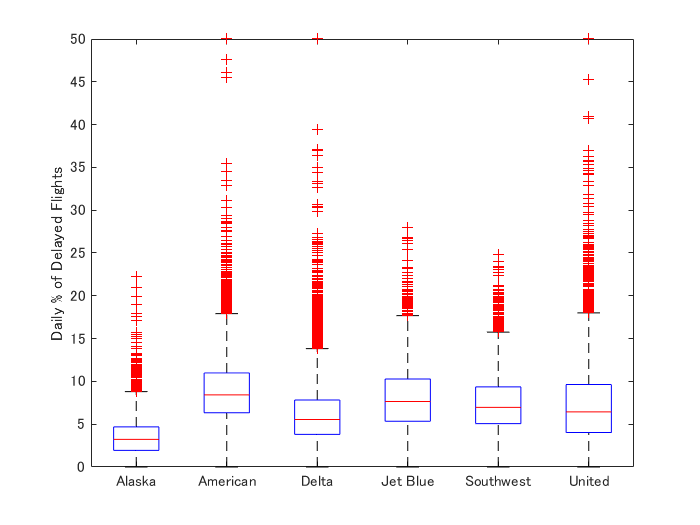

figure
boxplot(airline.pct_carrier_delay, airline.airline)
ylim([0,50])
ylabel('Daily % of Delayed Flights')

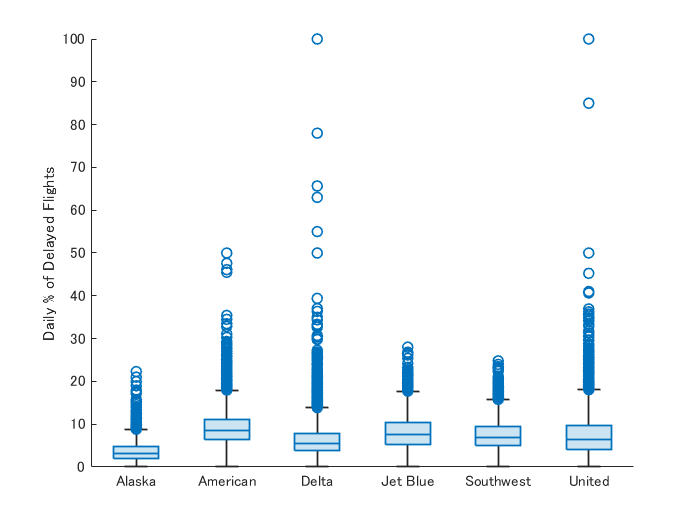

if ~verLessThan('matlab','9.8')
    % -- Code to run in MATLAB R2020a and later here --
    boxchart(airline.airline,airline.pct_carrier_delay)
    ylabel('Daily % of Delayed Flights')
end

航空会社別の遅延パーセントの箱ひげ図でした。バイオリンプロットを描く MATLAB 標準関数はないが、File Exchange や GitHub にはいくつか関数が散見されます。

- 例１：[https://github.com/bastibe/Violinplot-Matlab](https://github.com/bastibe/Violinplot-Matlab)

- 例２：[https://jp.mathworks.com/matlabcentral/fileexchange/23661-violin-plots-for-plotting-multiple-distributions-distributionplot-m](https://jp.mathworks.com/matlabcentral/fileexchange/23661-violin-plots-for-plotting-multiple-distributions-distributionplot-m)

## 1.8.4 多変量の可視化

再び `kc_tax.csv` から床面積と標準課税額のデータ。 ここでは ZipCode 別の分布を確認します。

kingCountry = readtable('..\psds_data\kc_tax.csv');
head(kingCountry)

ans = 8×3 table
    TaxAssessedValue    SqFtTotLiving    ZipCode
    ________________    _____________    _______

             NaN            1730          98117 
        2.06e+05            1870          98002 
        3.03e+05            1530          98166 
        3.61e+05            2000          98108 
        4.59e+05            3150          98108 
        2.23e+05            1570          98032 
        2.59e+05            1770          98168 
        1.75e+05            1150          98168 


非常に高額、広すぎる・狭すぎるデータは除く

tooExpensive = kingCountry.TaxAssessedValue > 750000;
tooBig = kingCountry.SqFtTotLiving > 3500;
tooSmall = kingCountry.SqFtTotLiving < 100;
subKingCountry = kingCountry(~tooExpensive & ~tooBig & ~tooSmall,:);
height(subKingCountry)

ans = 433838

ZipCode 別の床面積 vs 課税額の分布を可視化すると地域差が確認できます。

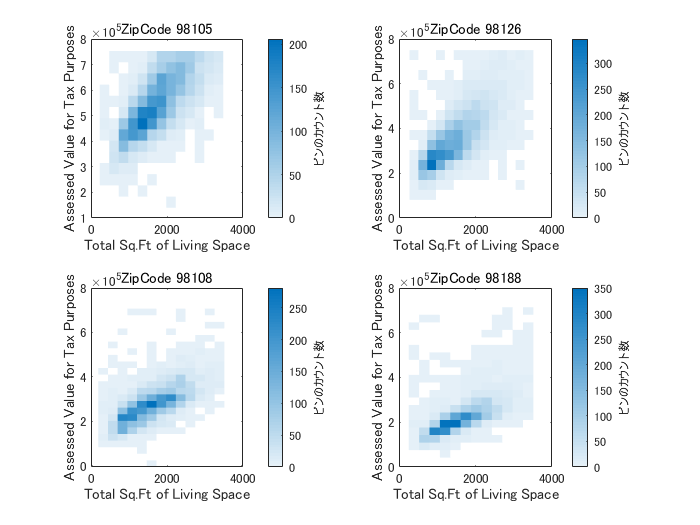

x = subKingCountry.SqFtTotLiving;
y = subKingCountry.TaxAssessedValue;
zip = subKingCountry.ZipCode;

figure
subplot(2,2,1);
idx = zip == 98105;
binscatter(x(idx),y(idx));
xlabel('Total Sq.Ft of Living Space')
ylabel('Assessed Value for Tax Purposes')
title('ZipCode 98105')

subplot(2,2,2);
idx = zip == 98126;
binscatter(x(idx),y(idx));
xlabel('Total Sq.Ft of Living Space')
ylabel('Assessed Value for Tax Purposes')
title('ZipCode 98126')

subplot(2,2,3);
idx = zip == 98108;
binscatter(x(idx),y(idx));
xlabel('Total Sq.Ft of Living Space')
ylabel('Assessed Value for Tax Purposes')
title('ZipCode 98108')

subplot(2,2,4);
idx = zip == 98188;
binscatter(x(idx),y(idx));
xlabel('Total Sq.Ft of Living Space')
ylabel('Assessed Value for Tax Purposes')
title('ZipCode 98188')